## FA4 strain

modelName = 'FA234';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')

set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','2') % FA4 model

set_param(modelName + "/Manual Switch3",'sw','0')
load("optInput_FA4.mat")
set_param(modelName + "/To test manually",'Value', num2str(optInput(1).Value)) % optimum for FA4

out{3} = sim('FA234.slx');

out = 1×3 の cell 配列
    {0×0 double}    {0×0 double}    {1×1 Simulink.SimulationOutput}


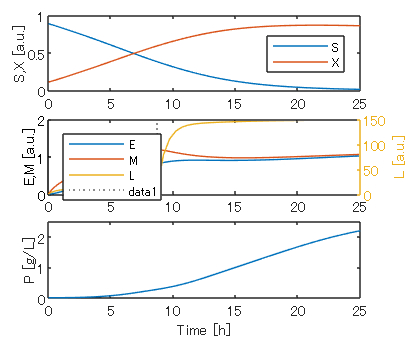

figure('Position', [100 100 300 250]);
t = tiledlayout(3,1,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';

nexttile
plot(out{3}.yout{1}.Values.Time,out{3}.yout{1}.Values.Data(:,[1 2]))
ylabel('S,X [a.u.]')
legend({'S' 'X'},'Location','east')

nexttile
plot(out{3}.yout{1}.Values.Time,out{3}.yout{1}.Values.Data(:,[3 4]))
ylim([0 2])
ylabel('E,M [a.u.]')

yyaxis right
plot(out{3}.yout{1}.Values.Time,out{3}.yout{1}.Values.Data(:,6))
ylabel('L [a.u.]')
legend({'E' 'M' 'L'},'Location','northwest')
xline(optInput(2).Value,':') % inducer 2 adding time

nexttile
plot(out{3}.yout{1}.Values.Time,out{3}.yout{1}.Values.Data(:,5))
ylim([0 2.5])
ylabel('P [g/L]')
xlabel('Time [h]')

## FA3 strain

set_param(modelName + "/Manual Switch1",'sw','1')

set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','1') % FA3 model

set_param(modelName + "/Manual Switch3",'sw','0')
load("optInput_FA3.mat")
set_param(modelName + "/To test manually",'Value', '100') % 100 uM IPTG for FA3

out{2} = sim('FA234.slx');

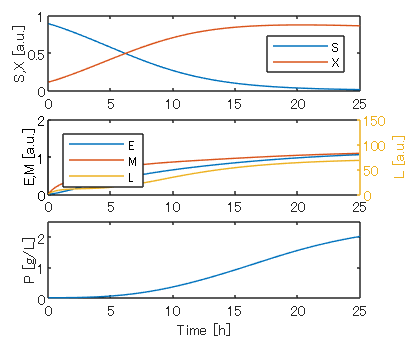

figure('Position', [100 100 300 250]);
t = tiledlayout(3,1,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';

nexttile
plot(out{2}.yout{1}.Values.Time,out{2}.yout{1}.Values.Data(:,[1 2]))
ylabel('S,X [a.u.]')
legend({'S' 'X'},'Location','east')

nexttile
plot(out{2}.yout{1}.Values.Time,out{2}.yout{1}.Values.Data(:,[3 4]))
ylim([0 2])
ylabel('E,M [a.u.]')

yyaxis right
plot(out{2}.yout{1}.Values.Time,out{2}.yout{1}.Values.Data(:,6))
ylabel('L [a.u.]')
ylim([0 150])
legend({'E' 'M' 'L'},'Location','northwest')
% xline(optInput(2).Value,':') % inducer 2 adding time

nexttile
plot(out{2}.yout{1}.Values.Time,out{2}.yout{1}.Values.Data(:,5))
ylim([0 2.5])
ylabel('P [g/L]')
xlabel('Time [h]')

## FA2 strain

set_param(modelName + "/Manual Switch1",'sw','1')

set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','0') % FA2 model

set_param(modelName + "/Manual Switch3",'sw','0')

load("optInput_FA2.mat")
set_param(modelName + "/To test manually",'Value','40') % 40 uM IPTG for FA2

out{1} = sim('FA234.slx');

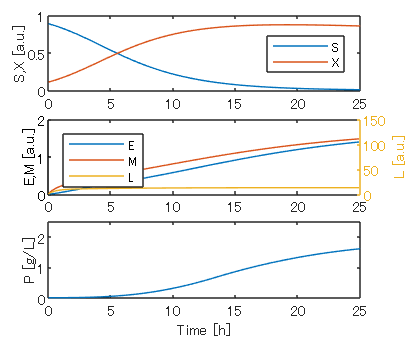

figure('Position', [100 100 300 250]);
t = tiledlayout(3,1,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';

nexttile
plot(out{1}.yout{1}.Values.Time,out{1}.yout{1}.Values.Data(:,[1 2]))
ylabel('S,X [a.u.]')
legend({'S' 'X'},'Location','east')

nexttile
plot(out{1}.yout{1}.Values.Time,out{1}.yout{1}.Values.Data(:,[3 4]))
ylim([0 2])
ylabel('E,M [a.u.]')

yyaxis right
plot(out{1}.yout{1}.Values.Time,out{1}.yout{1}.Values.Data(:,6))
ylabel('L [a.u.]')
ylim([0 150])
legend({'E' 'M' 'L'},'Location','northwest')
% xline(optInput(2).Value,':') % inducer 2 adding time

nexttile
plot(out{1}.yout{1}.Values.Time,out{1}.yout{1}.Values.Data(:,5))
ylim([0 2.5])
ylabel('P [g/L]')
xlabel('Time [h]')